fisTF = mamfis('Name','TempCO2FanController');
    
% Inputs
fisTF = addInput(fisTF,[-5 5],'Name','TemperatureError');
fisTF = addInput(fisTF,[-1000 1000],'Name','CO2Error');

% Temperature MFs
fisTF = addMF(fisTF,'TemperatureError','trimf',[-5 -5 0],'Name','Cold');
fisTF = addMF(fisTF,'TemperatureError','trimf',[-1 0 1],'Name','Normal');
fisTF = addMF(fisTF,'TemperatureError','trimf',[0 5 5],'Name','Hot');

% CO2 MFs
fisTF = addMF(fisTF,'CO2Error','trimf',[-1000 -1000 0],'Name','Low');
fisTF = addMF(fisTF,'CO2Error','trimf',[-300 0 300],'Name','OK');
fisTF = addMF(fisTF,'CO2Error','trimf',[0 1000 1000],'Name','High');

fisTF = addOutput(fisTF,[0 100],'Name','FanSpeed');

fisTF = addMF(fisTF,'FanSpeed','trimf',[0 0 25],'Name','OFF');
fisTF = addMF(fisTF,'FanSpeed','trimf',[20 40 60],'Name','LOW');
fisTF = addMF(fisTF,'FanSpeed','trimf',[50 70 90],'Name','MEDIUM');
fisTF = addMF(fisTF,'FanSpeed','trimf',[80 100 100],'Name','HIGH');

rulesTF = [
    "IF TemperatureError IS Cold AND CO2Error IS Low THEN FanSpeed IS OFF"
    "IF TemperatureError IS Cold AND CO2Error IS OK THEN FanSpeed IS LOW"
    "IF TemperatureError IS Cold AND CO2Error IS High THEN FanSpeed IS MEDIUM"

    "IF TemperatureError IS Normal AND CO2Error IS Low THEN FanSpeed IS LOW"
    "IF TemperatureError IS Normal AND CO2Error IS OK THEN FanSpeed IS LOW"
    "IF TemperatureError IS Normal AND CO2Error IS High THEN FanSpeed IS HIGH"

    "IF TemperatureError IS Hot AND CO2Error IS Low THEN FanSpeed IS MEDIUM"
    "IF TemperatureError IS Hot AND CO2Error IS OK THEN FanSpeed IS HIGH"
    "IF TemperatureError IS Hot AND CO2Error IS High THEN FanSpeed IS HIGH"
];

fisTF = addRule(fisTF, rulesTF);


T_measured = 28;
T_set = 26;
CO2_measured = 1300;
CO2_set = 800;

eT = T_measured - T_set;
eCO2 = CO2_measured - CO2_set;

fan_output = evalfis(fisTF,[eT eCO2])

fan_output = 92.0909

pwm_fan = round((fan_output/100)*255)

pwm_fan = 235

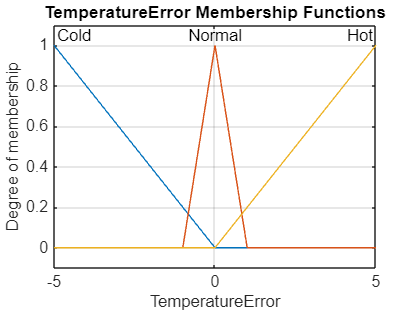

figure
plotmf(fisTF,'input',1)
title('TemperatureError Membership Functions')
grid on

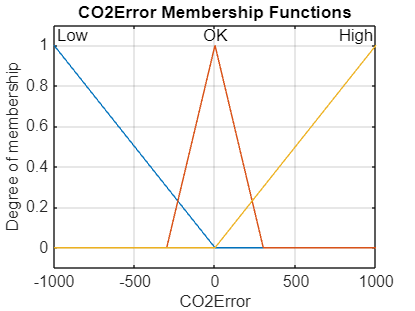


figure
plotmf(fisTF,'input',2)
title('CO2Error Membership Functions')
grid on

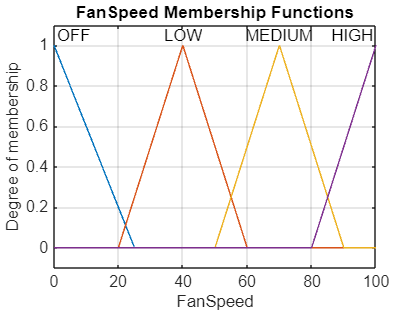


figure
plotmf(fisTF,'output',1)
title('FanSpeed Membership Functions')
grid on

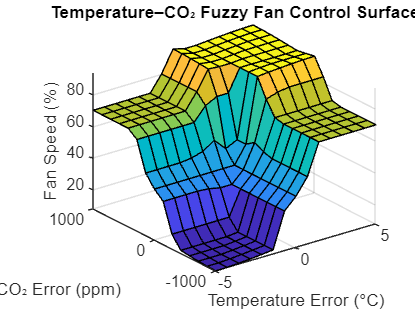


figure
gensurf(fisTF)
xlabel('Temperature Error (°C)')
ylabel('CO₂ Error (ppm)')
zlabel('Fan Speed (%)')
title('Temperature–CO₂ Fuzzy Fan Control Surface')